# **Circuitos Electricos II**

**Roberto Sanchez Figueroa    **

**brrsanchezfi@unal.edu.co**

***Monitoria Circuitos II***

***GIT-HUB:  https://github.com/brrsanchezfi/Circuitos_2022_1***

# **Soluciones propuestas para los ejercicios del taller 1**

#### PALABRAS CLAVES

reactancia, simulink, simscape, ltspice, matlab symbolic, numeros complejos, fasores.

## Solucion Numerica

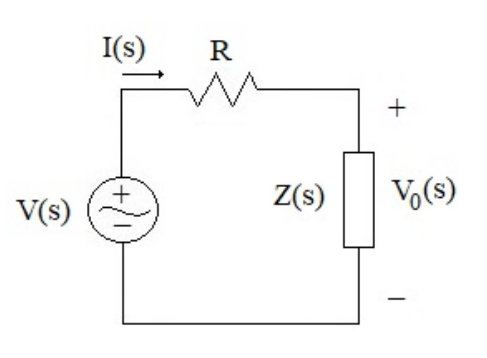

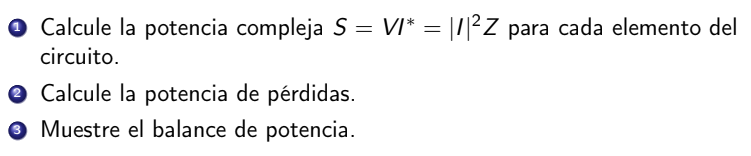

syms V I R Z V_0 s

%%%%___Valores propuestos___%%%%%
frecuencia = 60,

frecuencia = 60

V_s = pol_com(100,0);
R_n = 0.5;
Z_s = 2 + 10i;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

I_s =  (V_s/(Z_s + R_n))

I_s = 2.3529 - 9.4118i


%%%%___POTENCIA COMPLEJA___%%%%

sys_potencia_i =  (((V*Z)/(R+Z))*conj(I))

$$sys\_potencia\_i = \frac{V\,Z\,\bar{\text{I}}}{R+Z}$$

sys_potencia_i = subs(sys_potencia_i,[V I R Z],[V_s I_s R_n Z_s])

$$sys\_potencia\_i = \frac{3200}{17}+\frac{16000}{17}\,\mathrm{i}$$

sys_potencia_i = double(sys_potencia_i)

sys_potencia_i = 1.8824e+02 + 9.4118e+02i



%%%%___POTENCIAS DE PERDIDAS___%%%$

sys_perdidas = ((V*R)/(R+Z)*conj(I))

$$sys\_perdidas = \frac{R\,V\,\bar{\text{I}}}{R+Z}$$

sys_perdidas = subs(sys_perdidas,[V I R Z],[V_s I_s R_n Z_s])

$$sys\_perdidas = \frac{800}{17}$$

sys_perdidas = double(sys_perdidas)

sys_perdidas = 47.0588

%%%%___BALANCE DE POTENCIA___%%%%

sys_balance = V*conj(I) - (sys_perdidas + sys_potencia_i)

$$sys\_balance = V\,\bar{\text{I}}-\frac{4000}{17}-\frac{16000}{17}\,\mathrm{i}$$

sys_balance = subs(sys_balance,[V I R Z],[V_s I_s R_n Z_s])

$$sys\_balance = 0$$

sys_balance = double(sys_balance)

sys_balance = 0

## Simulacion 

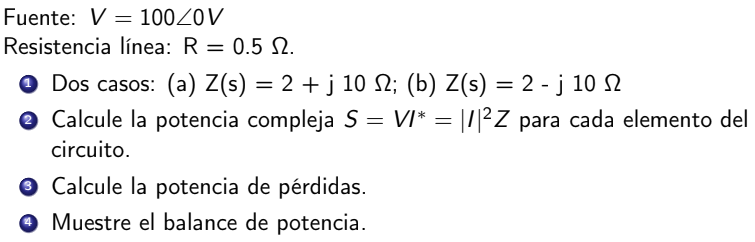

% Datos de simulacion
Frecuencia = 60; %Hz
V = pol_com(100,0);
R = 0.5;
Caso_1 = 2 + 10i; %Inductancia
    L = R_z(10,Frecuencia)

L = 0.0265

Caso_2 = 2 - 10i; %Capacitiva
    C = R_z(-10,Frecuencia)

C = 2.6526e-04

### CASO 1  

#### Simulink/Simscape

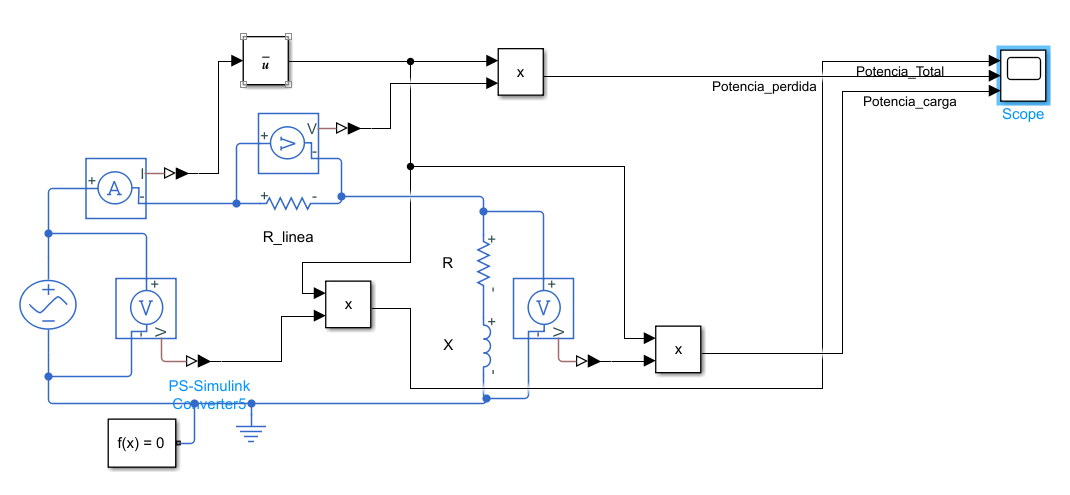

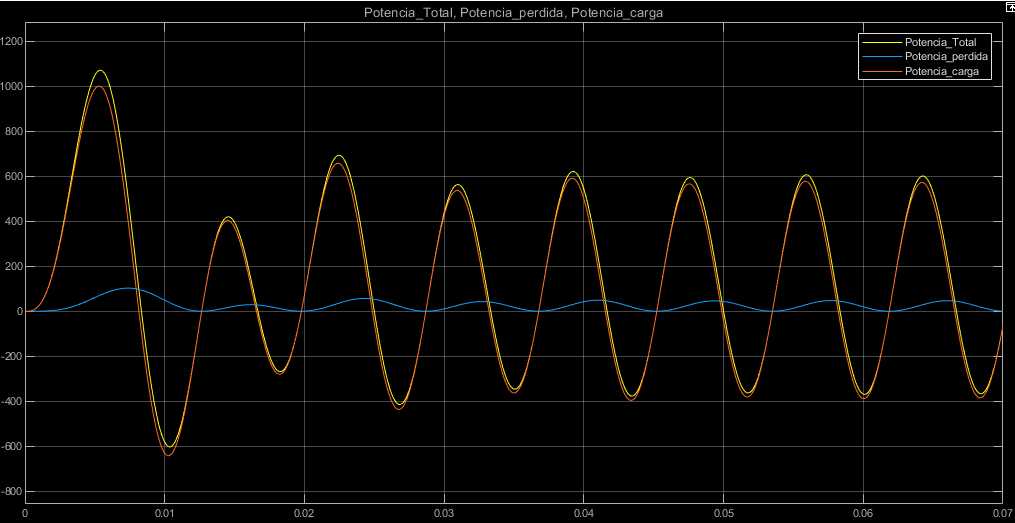

#### Ltspice

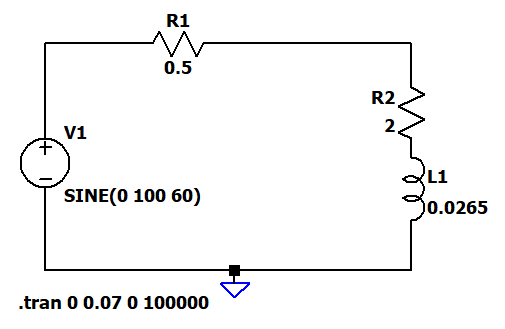

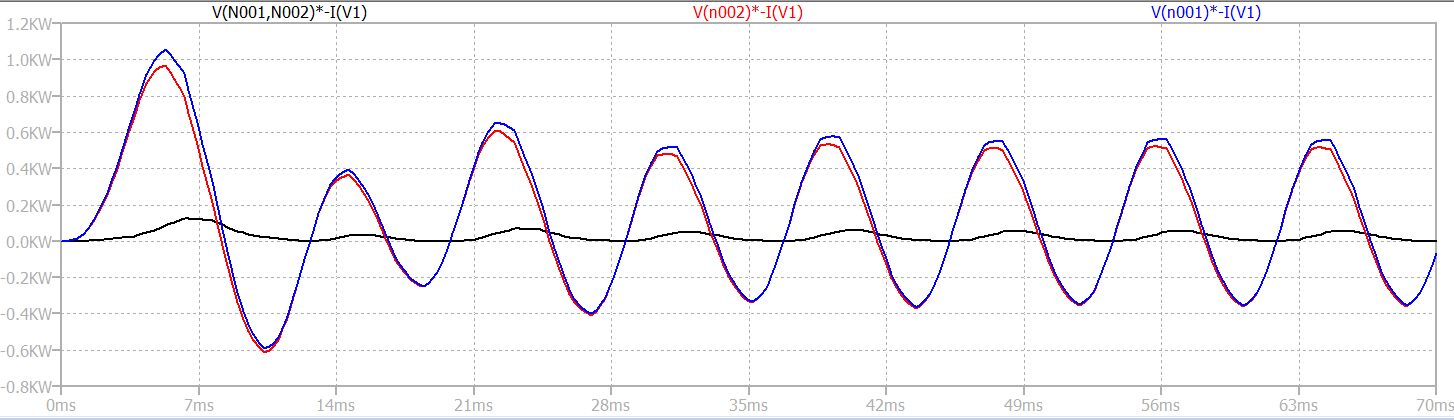

### CASO 2

#### Simulink/Simscape

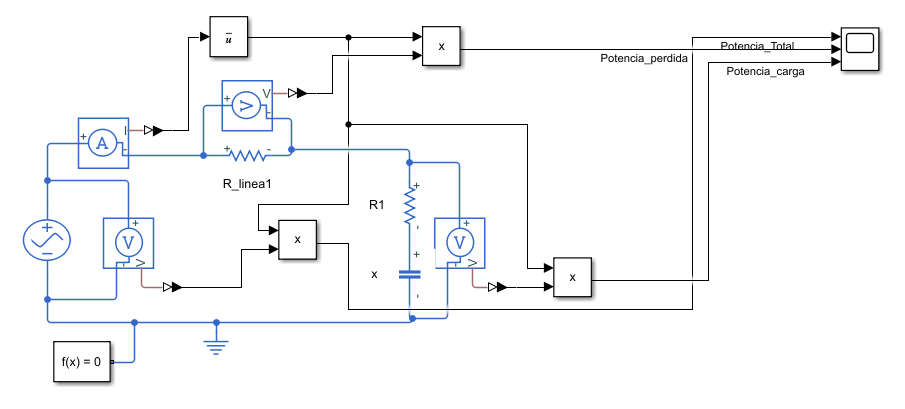

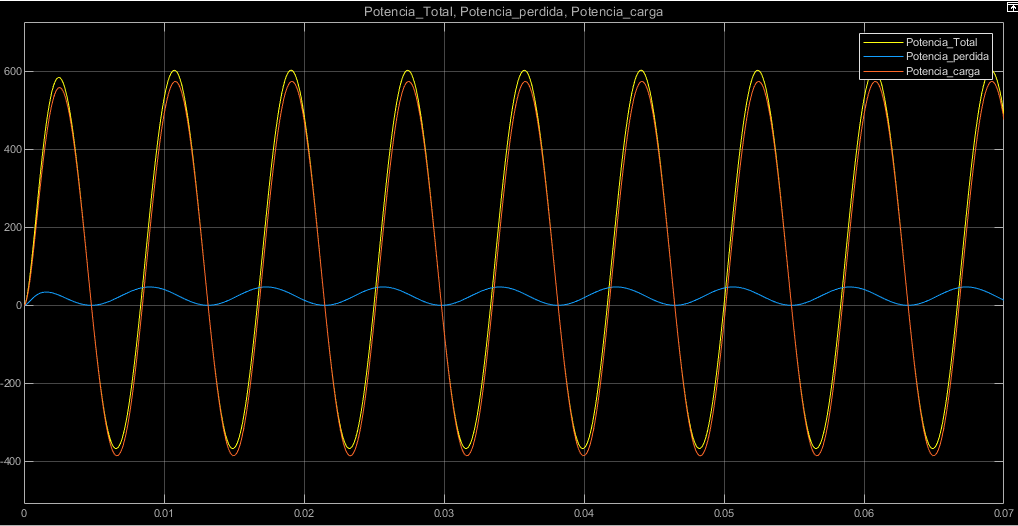

### Balance

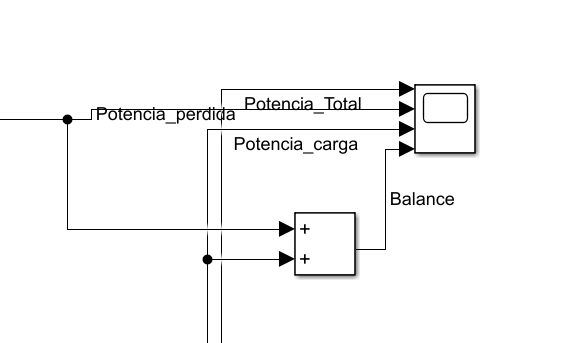

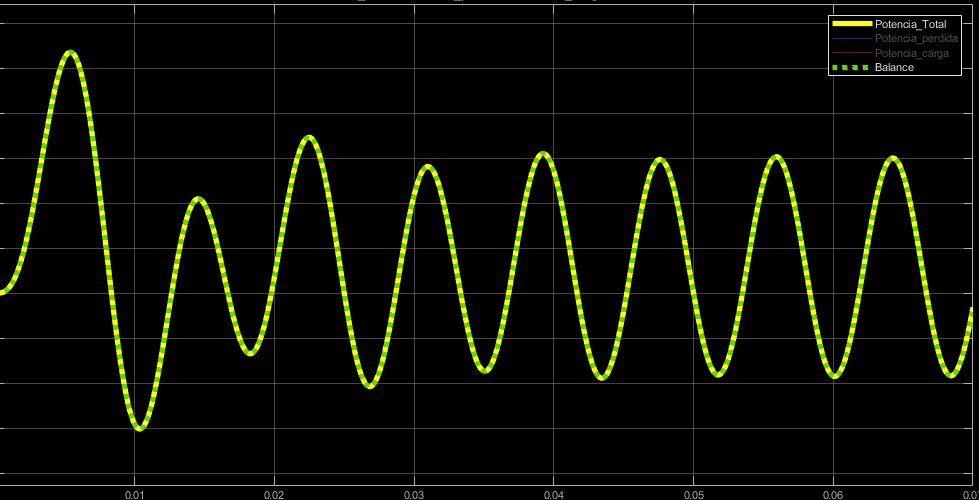

function Complejo = pol_com(M,A)  % magnitud, angulo

    Complejo = M * exp (deg2rad (A) * 1i); 

end


function Z_z = R_z(X,f) %reactancia, frecuencia hz
    
    if X > 0
    
        L = (X)/(2*pi*f);
        Z_z = L;
    
    elseif X < 0

        C = (1)/(2*pi*f*abs(X));
        Z_z = C; 
    
    else z == 0

        Z_z = z;

    end
end

